clear
clf
syms V(t) t m k V0 A(t)
V(t) = (V0 + 9.8*m/(k))*exp(-(k)/m*t)-9.8*m/(k);
A(t) = diff(V(t),t);

zero = solve(V(t) == 0,t);
dh(V0,k) = int(V(t),t,0,zero);
dh(V0,k) = subs(dh(V0,k),m,200)

$$dh(V0, k) = \frac{200\,V_{0}}{k}+\frac{392000\,\log\left(\frac{9800}{5\,V_{0}\,k+9800}\right)}{k^{2}}$$



kRange = 1:0.01:5

kRange =     1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000    1.1100    1.1200    1.1300    1.1400    1.1500    1.1600    1.1700    1.1800    1.1900    1.2000    1.2100    1.2200    1.2300    1.2400    1.2500    1.2600    1.2700    1.2800    1.2900    1.3000    1.3100    1.3200    1.3300    1.3400    1.3500    1.3600    1.3700    1.3800    1.3900    1.4000    1.4100    1.4200    1.4300    1.4400    1.4500    1.4600    1.4700    1.4800    1.4900


V0Range = (1:0.1:600)'

V0Range =     1.0000
    1.1000
    1.2000
    1.3000
    1.4000
    1.5000
    1.6000
    1.7000
    1.8000
    1.9000



[x1, x2] = meshgrid(V0Range,kRange)

x1 =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000
    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    

x2 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    


%x1 = repmat(V0Range,1,3)
%x2 = repmat(kRange,101,1)

g1 = gpuArray(x1);
g2 = gpuArray(x2);

LUT = double(arrayfun(@run, g2, g1))

LUT = <page truncated: showing [1:9, 1:123] of 401-by-5991>

  Columns 1 through 4

    0.0510    0.0617    0.0734    0.0862
    0.0510    0.0617    0.0734    0.0862
    0.0510    0.0617    0.0734    0.0862
    0.0510    0.0617    0.0734    0.0862
    0.0510    0.0617    0.0734    0.0862
    0.0510    0.0617    0.0734    0.0862
    0.0510    0.0617    0.0734    0.0862
    0.0510    0.0617    0.0734    0.0862
    0.0510    0.0617    0.0734    0.0862

  Columns 5 through 8

    0.1000    0.1147    0.1305    0.1474
    0.1000    0.1147    0.1305    0.1474
    0.1000    0.1147    0.1305    0.1474
    0.1000    0.1147    0.1305    0.1474
    0.1000    0.1147    0.1305    0.1474
    0.1000    0.1147    0.1305    0.1474
    0.0999    0.1147    0.1305    0.1474
    0.0999    0.1147    0.1305    0.1474
    0.0999    0.1147    0.1305    0.1474

  Columns 9 through 12

    0.1652    0.1841    0.2039    0.2248
    0.1652    0.1841    0.2039    0.2248
    0.1652    0.1841    0.2039    0.2248
    0.

LUT = gather(LUT)

LUT = 	1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002 

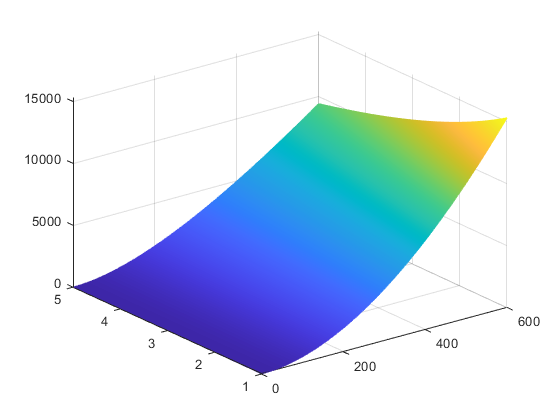


mesh(V0Range, kRange, LUT)


%V(t) = subs(V(t),[V0 m c k],[200 200 10 10]);
%A(t) = subs(A(t),[V0 m c k],[200 200 10 10]);

%tStep = 1/100;
%tStop = 60;
%realV = zeros(1,tStop/tStep + 1)
%realV(1) = V(0);
%h = waitbar(0,'Please wait...');
%const = -1 + tStop/tStep;
%for n = 2:1 + tStop/tStep
%    realV(n) = realV(n - 1) + (A(n*tStep) + A((n-1)*tStep))*tStep/2;
%    waitbar(n/const,h)
%end
%tempT = 0:tStep:tStop;
%plot(tempT,realV)
%hold on
%fplot(V(t),[0 tStop])
%hold off
%plot(abs(realV(int8(tempT/tStep + 1)) - V(tempT)))


function foo = run(k, V0)
 foo = (200*V0)/k + (392000*log(9800/(5*V0*k + 9800)))/k^2;
end